# **Modeling Gear Trains **

This problem aout the coumpound gear trains inside servomotors. Many devices such as radio controlled toys, remotely operated drones, and industrial automation requires that high torques are applied to attain a desired position and then feedback control is used ot hold that position.  In such cases, servomotors are frequently used in which a DC motor is combined with gearing to convert the relatively low torque and hign speed of the motor's shaft into higher torque and lower speed of the servo output.  The picture below shows an inexpesive commercially available servo with the upper case removed to reveal the compound gear train. 

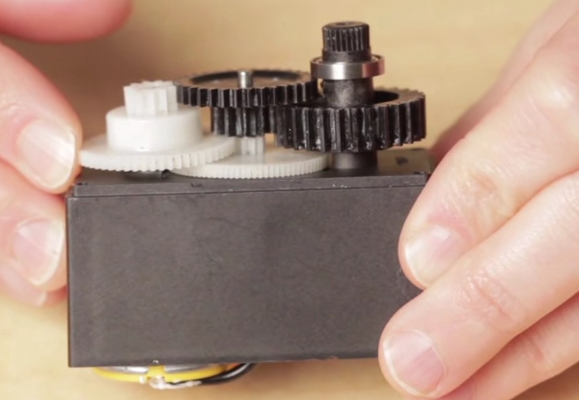

When one gear is mated to another gear, the each tooth on one gear engages with a single tooth on the other gear as the tooth passes through the area where the gears are in mesh.  As a result, you can infer the speed ratio of two mating gears just by counting the number of teeth on both gears.  For example, on the servo we are analyzing here, there is a small gear called a pinion attached to the motor and it has just 10 teeth.  That gear is mated to a much larger diameter gear with 72 teeth to the left of it in the picture below.  If the big gear goes around five complete revolutions, then 360 gear teeth had passed by the face of the smaller gear (since 5*72=360).  In order to stay in mesh, the smaller gear would have had to spin 36 revolutions since it has ten teeth and 36*10=360.   

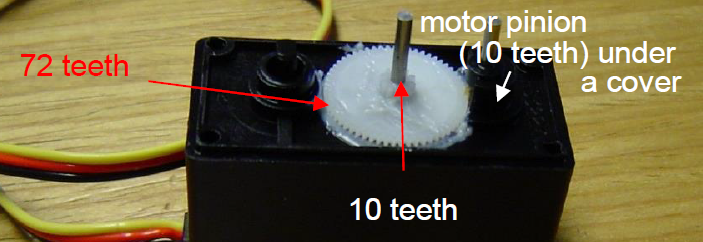.   

## Question 1

After the gear mesh described above, there is a 10 tooth gear that is firmly attached to the 72 tooth gear.  The 10 toot gear must turn at exactly the same rate as the 72 tooth gear.  The 10 tooth gear is then mated to a 48 tooth gear.  That 48 tooth gear must rotate at a speed 10/48 as fast as the previous gear in the train.  There is an 11 tooth gear that is firmly attached to the 48 tooth gear.  The 11 toot gear must turn at exactly the same rate as the 48 tooth gear.  The 11 tooth gear is then mated to a 36 tooth gear.  That 36 tooth gear must rotate at a speed 11/36 as fast as the previous gear in the train. There is a 16 tooth gear that is firmly attached to the 36 tooth gear.  The 16 tooth gear must turn at exactly the same rate as the 36 tooth gear.  The 16 tooth gear is then mated to 42 tooth gear.  That 42 tooth gear must rotate at a speed 16/42 as fast as the previous gear in the train.  That 42 tooth gear is attached to the output shaft of the motor.  What is the ratio of the speed of the motor shaft to the servo output shaft?

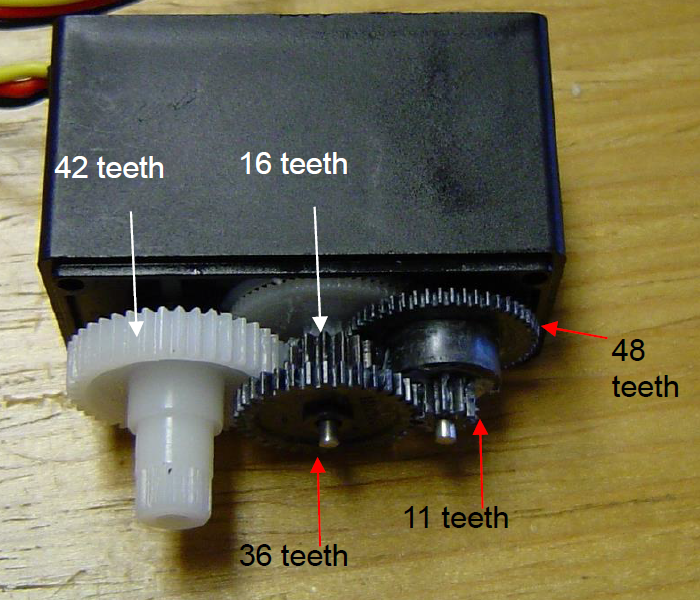 

%       Use this area to compute your solution  
speed_ratio=72*48*36*42 / (10*10*11*16) 

speed_ratio = 296.9018

## Question 2

The purpose of the gear train is to amplify torque generated by the electric motor. Let's first focus on estimating the torque produced by the DC motor.  A simple model of a DC motor is presented below.  An external voltage supply applies an electric potential to the terminals of the motor (indicated as $V$ in the model).  This applied voltage causes a current $I$ to flow through copper windings within the motor.  The flow of current near magnets in the motor leads to torque gererated at th motor's shaft according to the equation$\tau=K_tI$ where $K_t$ is the motor's "torque constant."  When the motor turns at a rate $\Omega$, there is a "back EMF" generated by motion of the windings near the magnets $E=K_t\Omega$ where once again $K_t$ is the motor's "torque constant."

The brushed DC motor in this servo has a torque constant of 0.0012 Newton Meters per Amp.  We used a 4.8V Nickel Metal Hydride battery. The winding resistance of the motor is 0.87 Ohms.  What is the current (in Amps) near “stall” when the output shaft is stationary or moving slowly?  What torque is produced by the the DC motor (in Newton meters)? 

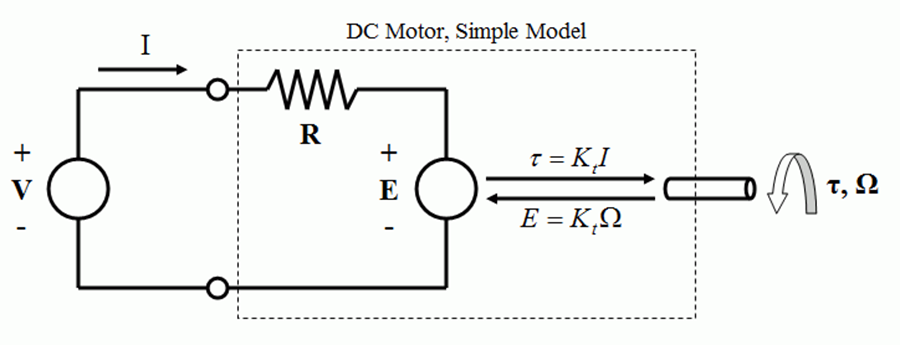

%       Use this area to compute your solution  
V=4.8; % Battery voltage (Volts)
R=0.87; % Winding resistance (Ohms)
I=V/R   % Current (Amps)

I = 5.5172

K_t=0.0012;  % Motor constant (Newton meters / Amp)
tau=K_t*I  % in Newton meters

tau = 0.0066

## Question 3

The amplification of torque in the gear train is relatively simple if we neglect friction.  If the friction in the gear train were negligible, we could infer from conservation of enegy that the power input at the motor output shaft equals the power delivered at the servo output shaft.  Shaft power is computer by mutiplying torque in units such as Newton meters by angular speed of the shaft in units like radians per second.  Given the ratio of the speeds we calculated previously (the motor shaft turns 297 times as fast as the sevo output), and assuming the motor shaft produces 0.03 Newton meters of torque, what would be the output torque of the servo if we could attain frictionless conditions? 

%       Use this area to compute your solution  
output_torque=tau*speed_ratio  % in Newton meters

output_torque = 1.9657

## Question 4

We can estimate the force applied by the motor pinion on the 72 tooth gear (we'll call it $F_{TL1}$) by assuming the force the force applied by the 72 tooth gear on the motor pinion is equal in magnitude and multiplying by the perpendicular distance to find the torque about the motor shaft.  Use the motor torque calculated in question 2 along with the radius of the pinion (2.0 mm) to estimate $F_{TL1}$.  

% write some code here
r_p=0.002;  % 2 millimeters
F_TL1=tau/r_p

F_TL1 = 3.3103

## Question 4

To make an initial estimate of output torque, we first assumed frictionless operation.  In reality, friction has a substantial effect on gear trains. Every gear is mounted on a shaft on which it rotates and which is subject to friction. Every mating set of teeth slide into and out of engagement resultng in frctional losses.  Therefore a more accurate model of a gear train must include these frictional effects.

Let’s make the model of just one pair of gears in the gear train, say the 10 teeth gear and 72 teeth molded together and represented schematically in the "Free Body Diagram" below.  One way to model the system is to posit that there are four forces acting on this single body having two gears molded together.  We can name these forces $F_{TL1}$ , $F_{TS1}$ , $F_{ShaftX1}$, and $F_{ShaftY1}$.  The force $F_{TL1}$ is a force tangent (the T is for tangent) to the gear pitch circle on the larger of the two gears (L is for large) and this is the second compound gear in the train (the 2 indicates its place in the sequence).  The force $F_{TS1}$ is a force tangent (the T is for tangent) to the gear pitch circle on the smaller of the two gears. The forces $F_{ShaftX1}$ and $F_{ShaftY1}$ are the X and Y components of the normal force applied to the gears at the shaft that supports them.  There are also frictional forces associated with the normal force supporting the shaft, but they are not separate unknowns, they are simply linked to the normal forces by the friction coefficient.  This completes the description of the forces in our model.  Those four forces ($F_{TL1}$ , $F_{TS1}$ , $F_{ShaftX1}$, and $F_{ShaftY1}$) appear in three different  equations.  One equation is determined by summing forces in the X direction and recognizing that sum must equal zero if the gear doesn't accelerate in the X direction (which itdoesn't under normal operation of the servo).  A second equation is determined by summing forces in the Y direction and recognizing that sum must equal zero if the gear doesn't accelerate in the Y direction (which itdoesn't under normal operation of the servo).  A third equation is determined by summing torques about the center of the gear and recognizing that sum must equal zero if the gear has zero angular accelerateion in the case of static torque application or else under steady operation at constant angular speed.

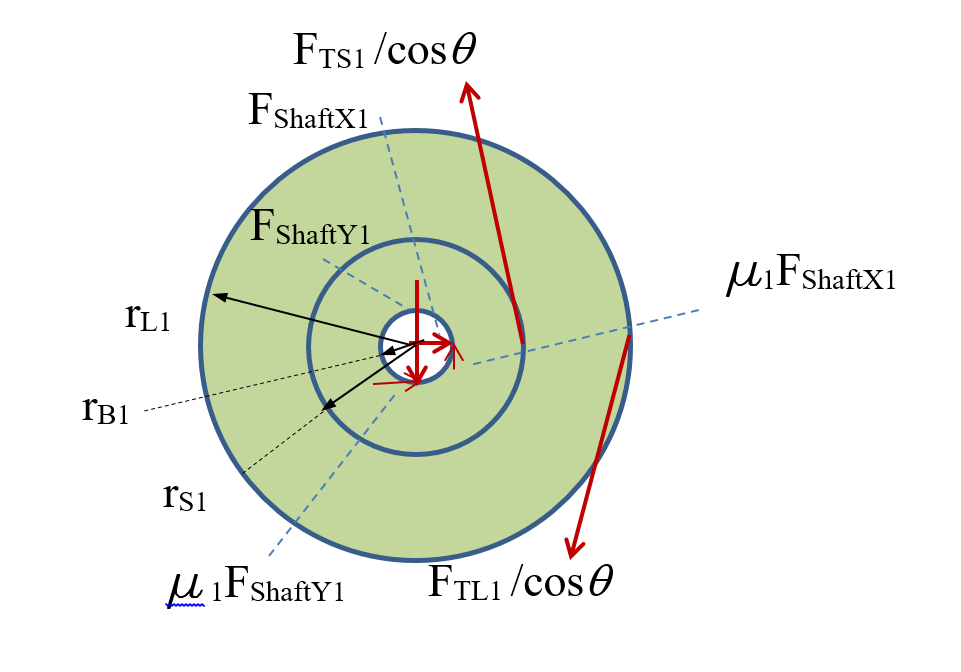

Model the three equations as a single matrix equation starting with the form given in the code below.  Note that $F_{TS1}$ is the tangent force.  Trigonometry will show that the entire force is $F_{TS1}/cos(\theta)$ and the separation force is $F_{TS1}tan(\theta)$ where  is the pressure angle of 20 degrees.

For the purposes of this exercise, we're setting up the problem up as if $F_{TL1}$ is known.  That the reason we're placing $F_{TL1}$ as part of th vector b on the right hand side of the equation.  Later you'll see why this simplifies the effort to find a solution.

% write some code here
theta=20;  % 20 degree pressure angle
mu1=0.0003;
r_b1=0.001; % 1 millimeter
r_L1=r_p*72/10;
r_S1=r_L1/5; % eyeballing
% A*x=b;
% x=[F_TS1;
%   F_ShaftX1; 
%   F_ShaftY1];
A=[  -tand(theta)    ,  +1    ,  -mu1    ;  % Sum forces in the X direction
      +1   ,  +mu1    ,  -1    ;  % Sum forces in the Y direction
       +r_S1  ,  +mu1*r_b1    , +mu1*r_b1     ]; % Sum torques about the center of rotation of gear 1
b=[ tand(theta);   +1   ;  +r_L1    ].*F_TL1;



## Question 6

Now, with a reasonable estimate in hand, we can assume $F_{TL1}$ is known.  In that case, the system of equations from question 4 can be solved at because it has three unknowns and three equations.  Find the values of   $F_{TS1}$ , $F_{ShaftX1}$, and $F_{ShaftY1}$. 

% write some code here
x=A\b;
F_TS1=x(1)

F_TS1 = 16.5496

F_ShaftX1=x(2) 

F_ShaftX1 = 7.2324

F_ShaftY1=x(3)

F_ShaftY1 = 13.2414

## Question 7

For the purposes of this exercise, it will be helpful to assume $F_{TL2}$ is known.   We can estimate its value of $F_{TL2}$ by assuming the contact between this gear and the mating pinion of the motor is 95% efficient.  Use the force $F_{TS1}$ calculated in question 2 to estimate $F_{TS1}$.  

% write some code here
eff=0.95;
F_TL2=F_TS1*eff

F_TL2 = 15.7221

## Question 8

Let's move on to th next pair of gears in the gear train which is the 11 teeth gear and 48 teeth molded together and represented schematically in the "Free Body Diagram" below.  One way to model the system is to posit that there are four forces acting on this single body having two gears molded together.  We can name these forces $F_{TL2}$ , $F_{TS2}$ , $F_{ShaftX2}$, and $F_{ShaftY2}$.  The force $F_{TL2}$ is a force tangent (the T is for tangent) to the gear pitch circle on the larger of the two gears (L is for large) and this is the second compound gear in the train (the 2 indicates its place in the sequence).  The force $F_{TS2}$ is a force tangent (the T is for tangent) to the gear pitch circle on the smaller of the two gears. The forces $F_{ShaftX2}$ and $F_{ShaftY2}$ are the X and Y components of the normal force applied to the gears at the shaft that supports them.  There are also frictional forces associated with the normal force supporting the shaft, but they are not separate unknowns, they are simply linked to the normal forces by the friction coefficient.  This completes the description of the unknown forces in our model.  Those four forces ($F_{TL2}$ , $F_{TS2}$ , $F_{ShaftX2}$, and $F_{ShaftY2}$) appear in three different  equations.  One equation is determined by summing forces in the X direction and recognizing that sum must equal zero if the gear doesn't accelerate in the X direction (which itdoesn't under normal operation of the servo).  A second equation is determined by summing forces in the Y direction and recognizing that sum must equal zero if the gear doesn't accelerate in the Y direction (which itdoesn't under normal operation of the servo).  A third equation is determined by summing torques about the center of the gear and recognizing that sum must equal zero if the gear has zero angular accelerateion in the case of static torque application or else under steady operation at constant angular speed.  

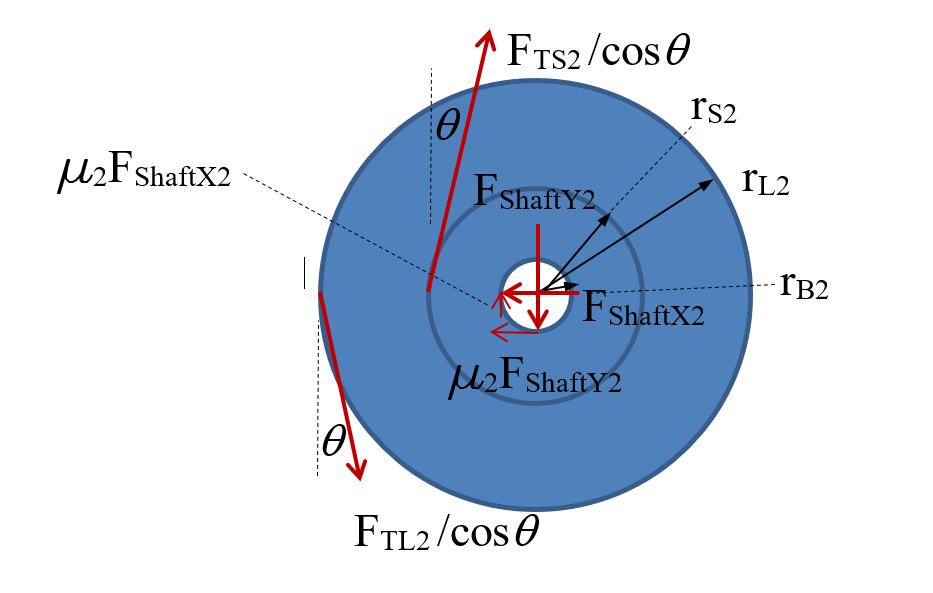

Model the three equations as a single matrix equation starting with the form given in the code below.  Note that $F_{TS2}$ is the tangent force.  Trigonometry will show that the entire force is $F_{TS2}/cos(\theta)$ and the separation force is $F_{TS2}tan(\theta)$ where  is the pressure angle of 20 degrees.

% write some code here

mu2=0.3;
r_b2=0.002; % 2 millimeters
r_L2=r_S1*48/10;
r_S2=r_L2/4; % eyeballing


% A2*x2=b2;
% x2=[F_TS2;
%   F_ShaftX2; 
%   F_ShaftY2];
A2=[  tand(theta)    ,  -1    ,  -mu2    ;  % Sum forces in the X direction
      +1   ,   +mu2   ,   -1   ;  % Sum forces in the Y direction
      +r_S2   ,  +mu2*r_b2    ,  +mu2*r_b2    ]; % Sum torques about the center of rotation of gear 1
b2=[ -tand(theta)     ;   +1   ;  +r_L2    ].*F_TL2;


## Question 9

Now, with a reasonable estimate in hand, we can assume $F_{TL2}$ is known.  In that case, the system of equations from question 8 can be solved at because it has three unknowns and three equations.  Find the values of   $F_{TS2}$ , $F_{ShaftX2}$, and $F_{ShaftY2}$. 

% write some code here
x2=A2\b2;
F_TS2=x2(1)

F_TS2 = 53.4660

F_ShaftX2=x2(2) 

F_ShaftX2 = 12.7149

F_ShaftY2=x2(3)

F_ShaftY2 = 41.5584

## Question 10

For the purposes of this exercise, it will be helpful to assume $F_{TL3}$ is known.  We can estimate its value of $F_{TL3}$ by assuming the contact between this gear and the mating pinion of the motor is 95% efficient.  Use the force $F_{TS2}$ calculated previously to estimate $F_{TL3}$.  

% write some code here
F_TL3=F_TS2*eff

F_TL3 = 50.7927

## Question 11

Let's move on to th next pair of gears in the gear train which is the 16 teeth gear and 36 teeth molded together and represented schematically in the "Free Body Diagram" below.  One way to model the system is to posit that there are four forces acting on this single body having two gears molded together.  We can name these forces $F_{TL3}$ , $F_{TS3}$ , $F_{ShaftX3}$, and $F_{ShaftY3}$.  The force $F_{TL3}$ is a force tangent (the T is for tangent) to the gear pitch circle on the larger of the two gears (L is for large) and this is the second compound gear in the train (the 2 indicates its place in the sequence).  The force $F_{TS3}$ is a force tangent (the T is for tangent) to the gear pitch circle on the smaller of the two gears. The forces $F_{ShaftX3}$ and $F_{ShaftY3}$ are the X and Y components of the normal force applied to the gears at the shaft that supports them.  There are also frictional forces associated with the normal force supporting the shaft, but they are not separate unknowns, they are simply linked to the normal forces by the friction coefficient.  This completes the description of the unknown forces in our model.  Those four forces ($F_{TL3}$ , $F_{TS3}$ , $F_{ShaftX3}$, and $F_{ShaftY3}$) appear in three different  equations.  One equation is determined by summing forces in the X direction and recognizing that sum must equal zero if the gear doesn't accelerate in the X direction (which itdoesn't under normal operation of the servo).  A second equation is determined by summing forces in the Y direction and recognizing that sum must equal zero if the gear doesn't accelerate in the Y direction (which itdoesn't under normal operation of the servo).  A third equation is determined by summing torques about the center of the gear and recognizing that sum must equal zero if the gear has zero angular accelerateion in the case of static torque application or else under steady operation at constant angular speed.  

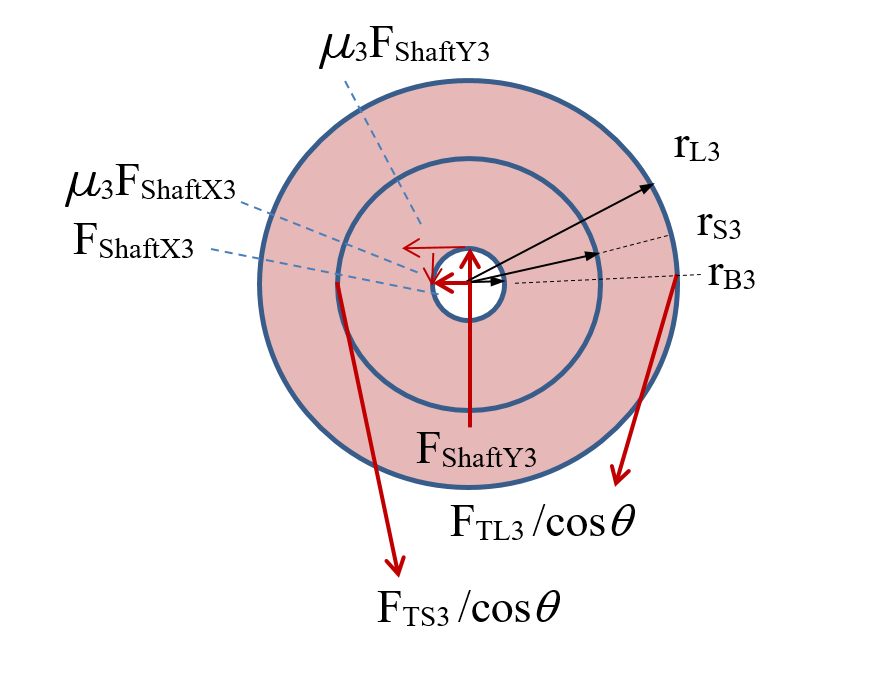

Model the three equations as a single matrix equation starting with the form given in the code below.  Note that $F_{TS3}$ is the tangent force.  Trigonometry will show that the entire force is $F_{TS3}/cos(\theta)$ and the separation force is $F_{TS3}tan(\theta)$ where  is the pressure angle of 20 degrees.

% write some code here
mu3=0.0003;
r_b3=0.002; % 2 millimeters
r_L3=r_S2*36/11;
r_S3=r_L3/4; % eyeballing
% A3*x3=b3;
% x3=[F_TS3;
%   F_ShaftX3; 
%   F_ShaftY3];
A3=[   -tand(theta)   ,    -1  ,  -mu3    ;  % Sum forces in the X direction
      -1   ,  -mu3    ,   +1   ;  % Sum forces in the Y direction
       r_S3  ,   +mu3*r_b3   ,  +mu3*r_b3    ]; % Sum torques about the center of rotation of gear 1
b3=[  +tand(theta)    ;  +1    ;   +r_L3   ].*F_TL3;



## Question 12

Now, with a reasonable estimate in hand, we can assume $F_{TL3}$ is known.  In that case, the system of equations from question 10 can be solved at because it has three unknowns and three equations.  Find the values of   $F_{TS3}$ , $F_{ShaftX3}$, and $F_{ShaftY3}$. 

% write some code here
x3=A3\b3;
F_TS3=x3(1)

F_TS3 = 203.1366

F_ShaftX3=x3(2) 

F_ShaftX3 = -92.4989

F_ShaftY3=x3(3)

F_ShaftY3 = 253.9015

## Question 13

To finally determine the output torque of the gear train,  We can estimate its value of $F_{TL3}$ by assuming the contact between this gear and the mating pinion of the motor is 95% efficient.  Use the force $F_{TS3}$ calculated previously to estimate $\tau_{out}$.  

% write some code here
F_TL4=eff*F_TS3

F_TL4 = 192.9797

## Question 14

What is the overall torque amplification of the gear train?  Is this value reasonable?   

% write some code here
r_L4=r_S3*42/16;
overall_ratio=F_TL4*r_L4/tau

overall_ratio = 216.3522

## Question 14

What is the overall efficiency of the gear train?  Is this value reasonable?   

% write some code here

overall_eff=overall_ratio/speed_ratio

overall_eff = 0.7287

## Question 15

Let's bring the overall model together.  Below is a code that repesents a solution for the complete gear train.  Let's run some checks on how reasonable the behavior is:

If the gear efficiency is 100% and coefficient of friction is 0, that should be the ratio on output torque to input torque?  Does the model behavior match?

% write some code here
speed_ratio=72*48*36*42 / (10*10*11*16)

speed_ratio = 296.9018

V=4.8; % Battery voltage (Volts)
R=0.87; % Winding resistance (Ohms)
I=V/R   % Current (Amps)

I = 5.5172

K_t=0.0012;  % Motor constant (Newton meters / Amp)
tau=K_t*I  % in Newton meters

tau = 0.0066

theta=20;  % 20 degree pressure angle
mu1=0.08;
r_b1=0.001; % 1 millimeter
r_p=0.002;  % 2 millimeters
r_L1=r_p*72/10;
r_S1=r_L1/5; % eyeballing
eff=0.98;
F_TL1=(tau/r_p)*eff

F_TL1 = 3.2441

A=[  -tand(theta)    ,  +1    ,  -mu1    ;  % Sum forces in the X direction
      +1   ,  +mu1    ,  -1    ;  % Sum forces in the Y direction
       +r_S1  ,  +mu1*r_b1    , +mu1*r_b1     ]; % Sum torques about the center of rotation of gear 1
b=[ tand(theta);   +1   ;  +r_L1    ].*F_TL1;
x=A\b;
F_TS1=x(1)

F_TS1 = 15.6389

F_ShaftX1=x(2) 

F_ShaftX1 = 7.9151

F_ShaftY1=x(3)

F_ShaftY1 = 13.0280

mu2=mu1;
r_b2=0.002; % 2 millimeters
r_L2=r_S1*48/10;
r_S2=r_L2/4; % eyeballing
F_TL2=F_TS1*eff

F_TL2 = 15.3262

A2=[  tand(theta)    ,  -1    ,  -mu2    ;  % Sum forces in the X direction
      +1   ,   +mu2   ,   -1   ;  % Sum forces in the Y direction
      +r_S2   ,  +mu2*r_b2    ,  +mu2*r_b2    ]; % Sum torques about the center of rotation of gear 1
b2=[ -tand(theta)     ;   +1   ;  +r_L2    ].*F_TL2;
x2=A2\b2;
F_TS2=x2(1)

F_TS2 = 58.1628

F_ShaftX2=x2(2) 

F_ShaftX2 = 23.1726

F_ShaftY2=x2(3)

F_ShaftY2 = 44.6905

mu3=mu1;
r_b3=0.002; % 2 millimeters
r_L3=r_S2*36/11;
r_S3=r_L3/4; % eyeballing
F_TL3=F_TS2*eff

F_TL3 = 56.9996

A3=[   -tand(theta)   ,    -1  ,  -mu3    ;  % Sum forces in the X direction
      -1   ,  -mu3    ,   +1   ;  % Sum forces in the Y direction
       r_S3  ,   +mu3*r_b3   ,  +mu3*r_b3    ]; % Sum torques about the center of rotation of gear 1
b3=[  +tand(theta)    ;  +1    ;   +r_L3   ].*F_TL3;
x3=A3\b3;
F_TS3=x3(1)

F_TS3 = 219.7980

F_TL4=eff*F_TS3;
r_L4=r_S3*42/16;
overall_ratio=F_TL4*r_L4/tau

overall_ratio = 241.4902

overall_eff=overall_ratio/speed_ratio

overall_eff = 0.8134

## Question 16

Let's consider some design issues:

Which shaft in he gear train had the largest power dissipation at the contact with the shaft?  If you could invest in improvements such as rolling element bearings for the gears, where would those investments pay off most, near the output or near the motor?

% write some code here